addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\in_progress_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\code_shared_groupNind
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\individual_analysis_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\group_analyses_code

% load individual vars into group cell arrays

% no pup, struct2
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupEarliestTrial, groupNumLateTrialsSubtract] = makeGroupStruct2_noPup();

% w/pup
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupEarliestTrial, groupNumLateTrialsSubtract] = makeGroupStruct2();

% old no pup data:
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();


% save all group vars

%save('n4_2ndExpt_305RT_305LT.mat','-v7.3') % '-append',

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons = {'V1','LM','RL','AM'}
cons4Legend
durs4Legend 

%durat = 1; % for any plotting functions, so they ignore extra durations for some mice

% group run distributions *all sess*

clear meanSpeedAllTrials_eachSess
meanSpeedAllTrials_eachSess = [];

clear n
for n = 1:nGroup
    
    % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
    nthMeanSpeedAllTrials = groupMeanSpeedAllTrials{1,n};
    meanSpeedAllTrials_eachSess = [meanSpeedAllTrials_eachSess,nthMeanSpeedAllTrials];
    numTrialsEachSess(1,n) = length(nthMeanSpeedAllTrials);
    
end 

numTrialsEachSess
meanNumTrialsPerSess = mean(numTrialsEachSess)
std_of_meanNumTrialsPerSess = std(numTrialsEachSess)

tot_num_trials = length(meanSpeedAllTrials_eachSess)

% "  if we want to say how widely scattered some measurements are, 
% we use the standard deviation. 
% If we want to indicate the uncertainty around the estimate of the mean measurement, 
% we quote the standard error of the mean."

% convert speed from pix/sec to cm/sec
%meanSpeedAllTrials_eachSess_in_cm = meanSpeedAllTrials_eachSess/60;

% run threshold & getting idx for hi & low state, per session

clear groupRunThresh
clear groupIdxRunTrials
clear groupIdxStatTrials

runThresh = 60 % 1 cm/sec = 60 pix/sec 

for n = 1:nGroup
    
    groupRunThresh{1,n} = runThresh;
    numTrials = length(groupMeanSpeedAllTrials{1,n});
    numTrialsOverThresh = sum(groupMeanSpeedAllTrials{1,n}>=runThresh);
    percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100;
    % indicies for trials that meet our threshold
    groupIdxRunTrials{1,n} = find(groupMeanSpeedAllTrials{1,n}>=runThresh);
    numRunTrials = length(groupIdxRunTrials{1,n});
    % indicies for stationary trials
    groupIdxStatTrials{1,n} = find(groupMeanSpeedAllTrials{1,n}<=runThresh);
    numStatTrials = length(groupIdxStatTrials{1,n});

end 


% PLOT group run dist

meanSpeedAllTrials_eachSess_in_cm = meanSpeedAllTrials_eachSess/60;

%Bin edges, specified as a vector. edges(1) is the left edge of the first bin, 
%and edges(end) is the right edge of the last bin.
edges = [0 0:0.5:max(meanSpeedAllTrials_eachSess_in_cm) max(meanSpeedAllTrials_eachSess_in_cm)];

lighter_blue = '[0.3010 0.7450 0.9330]';
global lighter_blue 
orange = '[0.9100 0.4100 0.1700]';
global orange
%blue = '[0 0.4470 0.7410]';


yMin = 0;
yMax = 0.5;
yLimit = [yMin yMax];

xMin = 0;
xMax = 10;
xLimit = [xMin xMax];

clear h
h = histogram(meanSpeedAllTrials_eachSess_in_cm,edges,'Normalization','probability','FaceColor',lighter_blue)
%h = histogram(meanSpeedAllTrials_eachSess_in_cm,edges)

ylim(yLimit)
xlim(xLimit)

hold on 
        
clear y_thresh
%y_thresh = [0:0.01:round(max(h.Values),2)+0.01];
y_thresh = [0:0.01:yMax];

clear x_thresh
x_thresh(1,1:length(y_thresh)) = runThresh/60; % convert threshold from pix to cm

plot(x_thresh,y_thresh,'color',orange,'lineWidth',3)

% num Trials across all sessions
numTrialsAcrossAllSess = size(meanSpeedAllTrials_eachSess_in_cm)

% visualization

fntSize = 10;
fntName = 'SansSerif';

set(gca, 'FontSize', fntSize, 'FontName', fntName)

fontMult = 1.5;

xlabel('speed (cm/sec)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
ylabel('frequency', 'FontSize', fntSize*fontMult, 'FontName', fntName)

yt = [0:0.1:yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

xt = [0:1:round(max(meanSpeedAllTrials_eachSess_in_cm))];
xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
set(gca,'xtick',xt); 
set(gca,'xticklabel',xtl);

%legend('speed','threshold', 'FontName', fntName)

% save plot
print('group21_RunDist.png','-dpng')


% % % group NON-norm pupil distributions *all sess*
% 
% meanPupDiameterAllTrials_eachSesss = [];
% 
% clear n
% for n = 1:nGroup
%     
%     % EXTRACT PEAK FRAMES BASELINE,and PTSDFOF
%     nthMeanPupDiameterAllTrials = groupMeanPupilDiameterAllTrials{1,n};
%     meanPupDiameterAllTrials_eachSesss = [meanPupDiameterAllTrials_eachSesss,nthMeanPupDiameterAllTrials];
%     
% end 
% 
% % group pupil dist
% edges = [0 0:1:max(meanPupDiameterAllTrials_eachSesss) max(meanPupDiameterAllTrials_eachSesss)];
% histogram(meanPupDiameterAllTrials_eachSesss,edges,'Normalization','probability')
% xlim([0 max(meanPupDiameterAllTrials_eachSesss)])
% %title('frequency of pupil diameters')
% %xlabel('pupil diamater (a.u.)')
% %ylabel('fraction of trials')
% 
% % visualization
% 
% grid on
% 
% set(gca, 'FontSize', fntSize, 'FontName', 'Times')
% 
% xlabel('$non-normalized pupil diameter (a.u.) $', 'Interpreter', 'latex')
% ylabel('$frequency$', 'Interpreter', 'latex')
% 
% % save plot
% %print('sinusoid_fig.png','-dpng')
% 

% % group run vs Non-norm pup scatter
% 
% figure
% scatter(meanSpeedAllTrials_eachSess,meanPupDiameterAllTrials_eachSesss)
% %xlabel('run speed (a.u.)')
% %ylabel('pupil diameter (a.u.)')
% 
% % visualization
% 
% grid on
% 
% set(gca, 'FontSize', 20, 'FontName', 'Times')
% 
% xlabel('$locomotion speed$', 'Interpreter', 'latex')
% ylabel('$non-normalized pupil diameter$', 'Interpreter', 'latex')
% 
% % save plot
% %print('sinusoid_fig.png','-dpng')

% normalizing pupil diameter

%% normalized group distribution of pupil diameter

clear h

p_hi = [99.95];

nbins = 50;

clear meanPupVal_normalized_allTrial_allSess
clear lessThan1_meanPupVal_normalized_allTrial_allSess
clear normalized_meanPupDiameterAllTrials_allSessAsOneVector
normalized_meanPupDiameterAllTrials_allSessAsOneVector = [ ];

for n = 1:nGroup;
    
    % get hi percentile value for nth session
    Percentile_hi = prctile(groupMeanPupilDiameterAllTrials{1,n},p_hi); 

    % normalize the pupil diamter vector for nth session (already set so min value = 0)
    % 'groupMeanPupilDiameterAllTrials{1,n}' is made in group analysis script
    % collect each session for scatter plot later
    meanPupVal_normalized_allTrial_allSess{1,n} = groupMeanPupilDiameterAllTrials{1,n}/Percentile_hi; % minimum is zero so don't need to subtract in num & denom
    % now have normalized pupil vector session 
    
    %% then filter out any normalized values greater than 1 (outliers)
    %lessThan1_percentile_idx = find(meanPupVal_normalized_allTrial_allSess{1,n}<1);
    %lessThan1_meanPupVal_normalized_allTrial_allSess{1,n} = meanPupVal_normalized_allTrial_allSess{1,n}(lessThan1_percentile_idx);
    
    % need this for setting x limit based on *all session* later:
    %normalized_meanPupDiameterAllTrials_allSessAsOneVector = [normalized_meanPupDiameterAllTrials_allSessAsOneVector,lessThan1_meanPupVal_normalized_allTrial_allSess{1,n}];
    normalized_meanPupDiameterAllTrials_allSessAsOneVector = [normalized_meanPupDiameterAllTrials_allSessAsOneVector, meanPupVal_normalized_allTrial_allSess{1,n}];
     
    % get histo output vals for each session 1st, so can set yMax on each subplot to the max
    % y value across all sessions
    %h = histogram(lessThan1_meanPupVal_normalized_allTrial_allSess{1,n},nbins,'normalization','probability');
    h = histogram(meanPupVal_normalized_allTrial_allSess{1,n},nbins,'normalization','probability');
    title('ignore, just for getting y_tot_max')
    % save max frequency value for each session, to use as max for
    % subplots later
    maxHvals_allSess(1,n) = max(h.Values);

end % end n loop


% PLOT *NORMALIZED* PUP HISTOS

%numTrials = length(meanSpeedAllTrials_eachSess_in_cm)/nGroup % mean num trials per sessin
%nbins = ceil(ceil(numTrials)/45) % denom is num trials per bin
edges = [0 0:0.01:max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)];
%y_tot_Max = round(max(maxHvals_allSess),2)+0.01; % maxHvals_allSess made in previos step, it's 1 x sessions
y_tot_Max = 0.125

numCol = 4; 
numRows = ceil(nGroup/numCol)+1;

pupThreshold = 0.5;

figure

for n = 1:nGroup

    if nGroup < 4
        
        subplot(2,2,n)  
        
        histogram(meanPupVal_normalized_allTrial_allSess{1,n},nbins,'normalization','probability')
        
        hold on 
        
        clear y_thresh
        y_thresh = [0:0.01:y_tot_Max];
        %y_thresh = [0:0.01:max(meanPupVal_normalized_allTrial_allSess{1,n})];
        
        clear x_thresh
        x_thresh(1,1:length(y_thresh)) = pupThreshold;
        
        plot(x_thresh,y_thresh,'r','lineWidth',1)
        
        ylim([0 y_tot_Max])
        ylabel('fraction of trials (*all* sessions)')
        
        xlim([min(normalized_meanPupDiameterAllTrials_allSessAsOneVector) max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)])
        xlabel('normalized pupil diameter (a.u.)')
        
        %set(gca,'xtick',xt); 
        %set(gca,'xticklabel',xtl);
        %set(gca,'YTick',yt)
        %axis square
        
    else
        
        subplot(numRows,numCol,n)
        histogram(meanPupVal_normalized_allTrial_allSess{1,n},nbins,'normalization','probability','FaceColor',lighter_blue)
        
        hold on 
        
        clear y_thresh
        y_thresh = [0:0.01:y_tot_Max];
        clear x_thresh
        x_thresh(1,1:length(y_thresh)) = pupThreshold;
        
        plot(x_thresh,y_thresh,'r','lineWidth',1)
        
        ylim([0 y_tot_Max]) 
        xlim([min(normalized_meanPupDiameterAllTrials_allSessAsOneVector) max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)]);
          
        grid on
        
        fntSize = 8;
        set(gca, 'FontSize', fntSize, 'FontName', 'Times')
        
%         yt = [0:0.02:round(y_tot_Max,2)+0.01];
%         ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
%         set(gca,'YTick',yt)
%         set(gca,'YTickLabel',ytl)
%         
%         xt = [0:0.25:1];
%         xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
%         set(gca,'xtick',xt); 
%         set(gca,'xticklabel',xtl);
% 
%         xlabel('$pupil \ size \ (a.u.)$', 'Interpreter', 'latex')
%         ylabel('$f$', 'Interpreter', 'latex')
        
        title(sprintf('$session$ %1.0d',n), 'Interpreter', 'latex')
        
        %legend({'$locomotion \ speed$','$running \ threshold$'}, 'Interpreter', 'latex')
        
        %axis square
        
    end % end if statement
    
end % end n loop

% if nGroup <4
%     
%     subplot(2,2,nGroup+1)
%     
%     histogram(normalized_meanPupDiameterAllTrials_allSessAsOneVector,nbins,'normalization','probability','FaceColor',blue)
%     
%     hold on 
%     
%     clear y_thresh
%     y_thresh = [0:0.01:round(y_tot_Max,2)+0.01];
%     clear x_thresh
%     x_thresh(1,1:length(y_thresh)) = 0.5;
%     
%     plot(x_thresh,y_thresh,'r','lineWidth',1)
%     
%     ylim([0 round(y_tot_Max,2)+0.01])
%     %ylabel('fraction of trials (*all* sessions)')
%     xlim([min(normalized_meanPupDiameterAllTrials_allSessAsOneVector)-0.01 max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)+0.01])
%     %xlabel('normalized pupil diameter (a.u.)')
%     title('all sessions')
%     
% else
% 
%     subplot(numRows,numCol,nGroup+1)
%     
%     histogram(normalized_meanPupDiameterAllTrials_allSessAsOneVector,nbins,'normalization','probability','FaceColor',blue)
%     
%     hold on 
%     
%     clear y_thresh
%     y_thresh = [0:0.01:round(y_tot_Max,2)+0.01];
%     clear x_thresh
%     x_thresh(1,1:length(y_thresh)) = 0.5;
%     
%     plot(x_thresh,y_thresh,'r','lineWidth',1)
%     
%     ylim([0 round(y_tot_Max,2)+0.01])
%     xlim([min(normalized_meanPupDiameterAllTrials_allSessAsOneVector)-0.01 max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)+0.01])
% 
%     grid on
%         
%     fntSize = 8;
%     set(gca, 'FontSize', fntSize, 'FontName', 'Times')
%     
%     yt = [0:0.02:round(y_tot_Max,2)+0.01];
%     ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
%     set(gca,'YTick',yt)
%     set(gca,'YTickLabel',ytl)
%     
%     xt = [0:0.25:1];
%     xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
%     set(gca,'xtick',xt); 
%     set(gca,'xticklabel',xtl);
% 
%     xlabel('$pupil \ size \ (a.u.)$', 'Interpreter', 'latex')
%     ylabel('$f$', 'Interpreter', 'latex')
%         
%     title('$all \ sessions$','Interpreter', 'latex')
%     
%     legend({'$pupil \ diameter$','$running \ pupil threshold$'}, 'Interpreter', 'latex')
% 
% end % end if nGroup statement
 
% save plot
%print('group_21_all_PupDist.png','-dpng')



% PLOT NORM PUP ALL SESS ONLY

light_red = [1 0.4 0.4];
global light_red
pea_green = [0.4 0.4 0];
global pea_green

numTrials = length(normalized_meanPupDiameterAllTrials_allSessAsOneVector) % num tot trials
%nbins = ceil(ceil(numTrials)/1000) % denom is num trials per bin
nbins = 40;
trial2binRatio = numTrials/nbins %edges = [0 0:0.03:max(normalized_meanPupDiameterAllTrials_allSessAsOneVector)];


% SET THRESH for PLOTting
pupThreshold = 0.4

yMin = 0;
yMax = 0.05;
yLimit = [yMin yMax];

xMin = 0;
xMax = max(normalized_meanPupDiameterAllTrials_allSessAsOneVector);
xLimit = [xMin xMax];

%%

figure
 
clear h
h = histogram(normalized_meanPupDiameterAllTrials_allSessAsOneVector,nbins,'normalization','probability','FaceColor',lighter_blue)
set(h, 'FaceColor', light_red);

maxHvals_allSessOneVector = max(h.Values);

hold on 

clear y_thresh
%y_thresh = [0:0.01:round(maxHvals_allSessOneVector,2)+0.01];
y_thresh = [0:0.01:yMax];
clear x_thresh
x_thresh(1,1:length(y_thresh)) = pupThreshold;

plot(x_thresh,y_thresh,'color',pea_green,'lineWidth',3)

%ylim([0 round(maxHvals_allSessOneVector,2)+0.01])
ylim(yLimit)
xlim(xLimit)

% visualization

fntSize = 10;
fntName = 'SansSerif';

set(gca, 'FontSize', fntSize, 'FontName', fntName)

fontMult = 1.5;

ylabel('frequency', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [0:0.01:yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

xlabel('pupil diameter (a.u.)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
xt = [0:0.2:xMax];
xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
set(gca,'xtick',xt); 
set(gca,'xticklabel',xtl);

legend('diameter','threshold', 'FontName', fntName)

% save plot
%print('group_21_PupDist.png','-dpng')

% Pupil threshold & indicies

clear groupPupThresh
clear groupIdxLargePupilTrials
clear groupIdxSmallPupilTrials

% define PUPIL THRESHold again, this time effects
% how trials are categorized (not just for plotting)
pupThreshold = 0.4

for n = 1:nGroup
    
    groupPupThresh{1,n} = pupThreshold; 
    % meanPupVal_normalized_allTrial_allSess{1,n} has all sessions and is created in previous block of percentile/normalization code
    numTrials = length(meanPupVal_normalized_allTrial_allSess{1,n});
    numTrialsOverThresh = sum(meanPupVal_normalized_allTrial_allSess{1,n}>=pupThreshold);
    percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100;
    % indicies for trials that meet our threshold
    groupIdxLargePupilTrials{1,n} = find(meanPupVal_normalized_allTrial_allSess{1,n}>=pupThreshold);
    numLargePupTrials = length(groupIdxLargePupilTrials{1,n});
    % indicies for stationary trials
    groupIdxSmallPupilTrials{1,n} = find(meanPupVal_normalized_allTrial_allSess{1,n}<=pupThreshold);
    numSmallPupTrials = length(groupIdxSmallPupilTrials{1,n});

end 

% plot run vs pup  traces 

light_red = [1 0.4 0.4];
pea_green = [0.4 0.4 0];

frameRate = (1/60); % 0.0167 sec per frame
pix2cmRatio = (1/60);
sec2min = (1/60);

fntSize = 10;
fontMult = 1.5;
subt4leg = 2;

fileNames = [1:1:nGroup];

%fntSize = 10;

%for n = 1:nGroup
for n = 1
    figure
    
    %st = suptitle(sprintf('%s $session$ %1.0d',groupSubjName{1,n},n));
    %set(st,'Interpreter','latex')

    % plot LOCO trace & thresh
    
    subplot(2,1,1)
    
    x_axis = 1:length(groupMeanSpeedAllTrials{1,n});
    plot(x_axis,groupMeanSpeedAllTrials{1,n}*pix2cmRatio,'color',lighter_blue,'LineWidth',2)
    
    hold on
    
    clear y
    y(1,1:length(groupMeanSpeedAllTrials{1,n}*pix2cmRatio)) = runThresh*pix2cmRatio;
    plot(x_axis,y,'color',orange,'LineWidth',2)

    % axes limits
     
    xMin = 0;
    xMax = length(x_axis);
    xlim([xMin xMax])
    
    %yMax = max(groupMeanSpeedAllTrials{1,n}*pix2cmRatio)+0.25;
    yMax = 8;
    yMin = 0;
    ylim([yMin yMax])
       
    % visualization
   
    fntName = 'SansSerif';
    set(gca, 'FontSize', fntSize, 'FontName', fntName)
    
    ylabel('speed (cm/sec)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
    yt = [0:2:yMax];
    ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
    set(gca,'YTick',yt)
    set(gca,'YTickLabel',ytl)
     
    xlabel('trial number', 'FontSize', fntSize*fontMult, 'FontName', fntName)
    xt = [0:400:xMax];
    xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);
    
    lgd1 = legend('speed','threshold','FontName', fntName);
    lgd1.FontSize = fntSize-subt4leg;
    
    % PUPIL 
    
    subplot(2,1,2)
    
    x_axis = 1:length(meanPupVal_normalized_allTrial_allSess{1,n});    
    plot(x_axis,meanPupVal_normalized_allTrial_allSess{1,n},'color',light_red,'LineWidth',2)
    
    hold on 
    
    clear y
    y(1,1:length(meanPupVal_normalized_allTrial_allSess{1,n})) = pupThreshold;
    plot(x_axis,y,'color',pea_green,'LineWidth',2)
    
    hold on
    
    % axes limits
    
    xMin = 0;
    xMax = length(x_axis);
    xlim([xMin xMax])
    
    %yMax = round(max(meanPupVal_normalized_allTrial_allSess{1,n}))+0.05;
    yMax = 1.2;
    yMin = 0;
    ylim([yMin yMax])
    
    % visualization
    
    fntName = 'SansSerif';
    set(gca, 'FontSize', fntSize, 'FontName', fntName)

    ylabel('pupil diameter (a.u.)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
    yt = [0:0.25:yMax];
    ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
    set(gca,'YTick',yt)
    set(gca,'YTickLabel',ytl)

    xlabel('trial number', 'FontSize', fntSize*fontMult, 'FontName', fntName)
    xt = [0:400:xMax];
    %xt = [0:5:ceil(length(meanPupVal_normalized_allTrial_allSess{1,n})*frameRate)];
    xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);

    lgd2 = legend('diameter','threshold','FontName', fntName);
    lgd2.FontSize = fntSize-subt4leg;
    %lgd3 = legend('threshold','color',pea_green);
    %set(lgd3,pea_green)
    %lgd3.FontSize = fntSize-subt4leg;

    % save plot
    nthFileName = sprintf('%d_fig.png',fileNames(n));
    %print(nthFileName,'-dpng')

end 


% %[R,PValue] = corrplot(X)
% X = [normalized_meanPupDiameterAllTrials_allSessAsOneVector;meanSpeedAllTrials_eachSess_in_cm];
% [R,PValue] = corrplot(X)
% 
% R = corrcoef(normalized_meanPupDiameterAllTrials_allSessAsOneVector,meanSpeedAllTrials_eachSess_in_cm)

%% pup vs run (norm or not) SCATTER (each sess overlaid)

figure

% for n = 1:nGroup
%     
%     % subplot dimensions based on number of sessions (plotting each session on one fig)
%     if nGroup < 4
%         subplot(1,nGroup+1,n)  
%     else
%         numCol = 5;
%         subplot(ceil(nGroup/numCol),5,n)
%     end 
% 
%     %scatter(groupMeanSpeedAllTrials{1,n},meanPupVal_normalized_allTrial_allSess{1,n})
%     scatter(meanRunVal_normalized_allTrial_allSess{1,n},meanPupVal_normalized_allTrial_allSess{1,n})
%     hold on
%     
%     clear x_thresh
%     x_thresh = [0:0.01:max(meanPupVal_normalized_allTrial_allSess{1,n})];
%     clear y_thresh
%     y_thresh(1,1:length(x_thresh)) = 0.5;
%     
%     plot(x_thresh,y_thresh,'m','lineWidth',1)
%     
%     xlabel('normalized locomotion speed')
%     ylabel('normalized pupil diameter')
%     formatSpec = 'session %1.0d';
%     titleText = sprintf(formatSpec,n);
%     title(titleText)
%     
%     ylim([0 1.2])
%     xlim([0 1.2])
%     
%     hold on
% 
% end 

for n = 1:nGroup
    
%     % subplot dimensions based on number of sessions (plotting each session on one fig)
%     if nGroup < 4
%         subplot(1,nGroup+1,nGroup+1)  
%     else
%         numCol = 5;
%         subplot(ceil(nGroup/numCol),5,nGroup+1)
%     end 
    
    %scatter(groupMeanSpeedAllTrials{1,n},meanPupVal_normalized_allTrial_allSess{1,n})
    h = scatter(groupMeanSpeedAllTrials{1,n}*pix2cmRatio,meanPupVal_normalized_allTrial_allSess{1,n},'.')
    h.SizeData = 1; 
    
    hold on
    
end 

hold on

clear y_pupThresh_line
y_pupThresh_line(1,1:length(meanSpeedAllTrials_eachSess_in_cm)) = pupThreshold;
x_pupThresh_line = [min(meanSpeedAllTrials_eachSess_in_cm):1:length(meanSpeedAllTrials_eachSess_in_cm)-1];

plot(x_pupThresh_line,y_pupThresh_line,'m','LineWidth',1)

hold on 

clear x_runThresh_line
y_runThresh_line = [0:0.1:1.2];
x_runThresh_line(1,1:length(y_runThresh_line)) = runThresh*pix2cmRatio;

plot(x_runThresh_line,y_runThresh_line,'g','LineWidth',1)
      
ylim([0 1.2])
xlim([0 max(meanSpeedAllTrials_eachSess_in_cm)])
    
grid on

fntSize = 10;
set(gca, 'FontSize', fntSize, 'FontName', 'Times')

ylabel('$pupil \ diameter \ (a.u.) $', 'Interpreter', 'latex')
xlabel('$locomotion \ (cm/sec)$', 'Interpreter', 'latex')  
%legend({'$running \ threshold$'}, 'Interpreter', 'latex')
            
% save plot
%print('groupPupRunScatter_fig.png','-dpng')

% scatter, all sess together

%purple = [0.4941 0.1843 0.5569];

lineSz = 2

figure

h = scatter(meanSpeedAllTrials_eachSess_in_cm, normalized_meanPupDiameterAllTrials_allSessAsOneVector,'k')
h.SizeData = lineSz;
h.Marker = '.';

hold on

% axes limits

xMin = 0;
xMax = ceil(max(meanSpeedAllTrials_eachSess_in_cm));
xlim([xMin xMax])

yMax = round(max(normalized_meanPupDiameterAllTrials_allSessAsOneVector))+0.1;
yMin = 0;
ylim([yMin yMax])

% thresh lines

clear y_pupThresh_line
y_pupThresh_line(1,1:ceil(max(meanSpeedAllTrials_eachSess_in_cm))+1) = pupThreshold;
x_pupThresh_line = [min(meanSpeedAllTrials_eachSess_in_cm):1:ceil(max(meanSpeedAllTrials_eachSess_in_cm))];

plot(x_pupThresh_line,y_pupThresh_line,'color',pea_green,'LineWidth',lineSz)

hold on 

clear x_runThresh_line
y_runThresh_line = [0:0.1:yMax];
x_runThresh_line(1,1:length(y_runThresh_line)) = runThresh*pix2cmRatio;

plot(x_runThresh_line,y_runThresh_line,'color',orange,'LineWidth',lineSz)
      
% visualization

fntSize = 10;
fontMult = 1.5;
%subt4leg = 0;

fntName = 'SansSerif';
set(gca, 'FontSize', fntSize, 'FontName', fntName)

ylabel('pupil diameter (a.u.)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [0:0.2:yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)
 
xlabel('speed (cm/sec)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
xt = [0:2:xMax];
xtl = arrayfun(@num2str, xt, 'UniformOutput', 0);
set(gca,'xtick',xt); 
set(gca,'xticklabel',xtl);

lgd = legend('trial','speed threshold','diameter threshold','FontName', fntName);
lgd.FontSize = fntSize-subt4leg;

% save plot
%print('n21_groupPupRunScatter.png','-dpng')

% HISTOs (need for stats stuff too) - # trials also in this code...

% LOCO

% getting distribtiion of trials via groupHisto() function
% plotting histos **AND** getting number of trials across all points, conditions etc

%durat = 1:length(uniqueDurations);
durat = 1
cont = 1:length(uniqueContrasts)
%cont = 7
visArea = 1:length(groupRoundYpts{1})
%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

sess = 1:nGroup

state = 'loRun'
[loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiRun'
[hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}


areaLabels = {'V1','LP','AL','AM','NV'};

% LOCO PLOT

yMax = 0.25;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

% HISTO FIGS & num TRIAL matricies

clear loco_lo_numTrialsAllSess_AllConsAllPt
clear loco_lo_sumTrialsAcrossSess_AllConsAllPts
clear loco_lo_mnDf_allConsAllPt
clear loco_lo_stderr_allConsAllPt

clear loco_hi_numTrialsAllSess_AllConsAllPt
clear loco_hi_sumTrialsAcrossSess_AllConsAllPts
clear loco_hi_mnDf_allConsAllPt
clear loco_hi_stderr_allConsAllPt

clear d
for d = durat
   
    clear i
    %visArea = 5;
    for i = visArea 
    %for i = 1
        
        fig2 = figure;
        
        state = 'both';
        formatSpec = 'Locmotion: %s'; % \n
        titleText = sprintf(formatSpec,areaLabels{i});
        suptitle(titleText)
      
        clear lo_numTrialsAllSess_AllConsOnePt
        clear hi_numTrialsAllSess_AllConsOnePt
        
        clear lo_sumTrialsAcrossSess_AllConsOnePt 
        clear hi_sumTrialsAcrossSess_AllConsOnePt 
        
        clear lo_mnDf_allConsOnePt
        clear hi_mnDf_allConsOnePt
        
        clear lo_stderr_allConsOnePt
        clear hi_stderr_allConsOnePt
                 
        clear c
        for c = cont
            
            % emty matricies to add different number of trials to each time thru sessions loop (below)
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            clear n
            for n = sess
  
                % get values for *all* sesson, cth dth ith trials, lo state
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for *nth* trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllConsOnePt(n,c) = length(loRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                % get values for all sesson, cth dth ith trials, hi state
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllConsOnePt(n,c) = length(hiRun_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT  
            % save number of trials across all sessions for each contrast
            lo_sumTrialsAcrossSess_eachConOnePt = sum(lo_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING num trials across at sess for each contrast
            lo_sumTrialsAcrossSess_AllConsOnePt(1,c) = lo_sumTrialsAcrossSess_eachConOnePt;
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast  
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % CALC & COLLECT each MEAN Df across all sessions for cth con, ith point 
            lo_mnDf_eachConOnePt = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allConsOnePt(1,c) = lo_mnDf_eachConOnePt;
       
            y = 0;
            hold on
                
            % COLLECT
            lo_stderr_eachConOnePt = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(lo_sumTrialsAcrossSess_eachConOnePt));
            % COLLECTING
            lo_stderr_allConsOnePt(1,c) = lo_stderr_eachConOnePt;
            
            h2 = scatter(lo_mnDf_eachConOnePt,y,'*','r');
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachConOnePt = sum(hi_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllConsOnePt(1,c) = hi_sumTrialsAcrossSess_eachConOnePt;
                   
            % PLOT one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))    
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachConOnePt = mean(hi_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            hi_mnDf_allConsOnePt(1,c) = hi_mnDf_eachConOnePt;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachConOnePt = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsAcrossSess_eachConOnePt));
            % COLLECTING
            hi_stderr_allConsOnePt(1,c) = hi_stderr_eachConOnePt;
            
            h4 = scatter(hi_mnDf_eachConOnePt,y,'*','g');
            %formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},lo_mnDf_eachConOnePt,lo_stderr_eachConOnePt,hi_mnDf_eachConOnePt,hi_stderr_eachConOnePt,lo_sumTrialsAcrossSess_eachConOnePt,hi_sumTrialsAcrossSess_eachConOnePt));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop

        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        loco_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = lo_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        loco_lo_sumTrialsAcrossSess_AllConsAllPts = squeeze(loco_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        loco_lo_numTrialsAllSess_AllConsAllPt(:,:,i) = lo_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        loco_lo_mnDf_allConsAllPt(i,:) = lo_mnDf_allConsOnePt;
        % mean sterr all points/cons
        loco_lo_stderr_allConsAllPt(i,:) = lo_stderr_allConsOnePt;
        
        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        loco_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = hi_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        loco_hi_sumTrialsAcrossSess_AllConsAllPts = squeeze(loco_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        loco_hi_numTrialsAllSess_AllConsAllPt(:,:,i) = hi_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        loco_hi_mnDf_allConsAllPt(i,:) = hi_mnDf_allConsOnePt;
        % mean sterr all points/cons
        loco_hi_stderr_allConsAllPt(i,:) = hi_stderr_allConsOnePt;
        

    end % end i loop

end % end d loop

% lo
% each sess
size(loco_lo_numTrialsAllSess_AllConsAllPt);
% across sess
size(loco_lo_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(loco_lo_mnDf_allConsAllPt);
% stderr each con across sess
size(loco_lo_stderr_allConsAllPt);

% hi
% each sess
size(loco_hi_numTrialsAllSess_AllConsAllPt);
% across sess
size(loco_hi_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(loco_hi_mnDf_allConsAllPt);
% stderr each con across sess
size(loco_hi_stderr_allConsAllPt);


% save plot
%print('groupLocoHistoV1_fig.png','-dpng')

lo_loco_mnNumTrialsPerStimCond_ = mean(loco_lo_sumTrialsAcrossSess_AllConsAllPts(1,:))
lo_loco_SD_MnNumTrialsPerStimCond = std(loco_lo_sumTrialsAcrossSess_AllConsAllPts(1,:))

hi_loco_mnNumTrialsPerStimCond_ = mean(loco_hi_sumTrialsAcrossSess_AllConsAllPts(1,:))
hi_loco_SD_MnNumTrialsPerStimCond = std(loco_hi_sumTrialsAcrossSess_AllConsAllPts(1,:))


% PUPIL histo

% getting distribtiion of trials via groupHisto() function
% plotting histos **AND** getting number of trials across all points, conditions etc

state = 'loPup'
[loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}
state = 'hiPup'
[hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial] = Histo_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxLargePupilTrials,groupIdxSmallPupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial = size(hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial)
% tip - index like this -
% allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}


% PLOT PUP histo

yMax = 0.25;
yLimit = [0 yMax];

xMax = 0.225;
xMin = -0.1;
xLimit = [xMin xMax];

xTickRange = [xMin:0.05:xMax];
xTickLabelRange = [xMin:0.05:xMax];

edgeWidth = 0.01;
edges = [xMin xMin:edgeWidth:xMax xMax];
%numBins = 25;

% HISTO FIGS & num TRIAL matricies

clear pup_lo_numTrialsAllSess_AllConsAllPt
clear pup_lo_sumTrialsAcrossSess_AllConsAllPts
clear pup_lo_mnDf_allConsAllPt
clear pup_lo_stderr_allConsAllPt

clear pup_hi_numTrialsAllSess_AllConsAllPt
clear pup_hi_sumTrialsAcrossSess_AllConsAllPts
clear pup_hi_mnDf_allConsAllPt
clear pup_hi_stderr_allConsAllPt

clear d
for d = durat
   
    clear i

    for i = visArea 

        fig2 = figure;
        
        state = 'both';
        %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
        formatSpec = 'Pup: area=%1.0f durat=%1.0f state=%s ew=%0.3f'; % \n
        titleText = sprintf(formatSpec,i,d,state,edgeWidth);
        %suptitle(titleText)
      
        clear pup_lo_numTrialsAllSess_AllConsOnePt
        clear pup_lo_sumTrialsAcrossSess_AllConsOnePt 
        
        clear pup_lo_numTrialsAllSess_AllConsOnePt
        clear pup_lo_sumTrialsAcrossSess_AllConsOnePt
        
        clear pup_lo_mnDf_allConsOnePt
        clear pup_hi_mnDf_allConsOnePt
        
        clear pup_lo_stderr_allConsOnePt
        clear pup_hi_stderr_allConsOnePt
                 
        clear c
        for c = cont
            
            % emty matricies to add different number of trials to each time thru sessions loop (below)
            clear lo_dthithCthNth_pkDfEachTrial
            lo_dthithCthNth_pkDfEachTrial = []; 
        
            clear hi_dthithCthNth_pkDfEachTrial
            hi_dthithCthNth_pkDfEachTrial = [];
             
            clear n
            for n = sess
  
                % get values for *all* sesson, cth dth ith trials, lo state
                lo_dthithCthNth_pkDfEachTrial = [lo_dthithCthNth_pkDfEachTrial,loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for *nth* trial, cth contrast, save num of trials at this contrast
                % num trials this n this c
                lo_numTrialsAllSess_AllConsOnePt(n,c) = length(loPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
                % get values for all sesson, cth dth ith trials, hi state
                hi_dthithCthNth_pkDfEachTrial = [hi_dthithCthNth_pkDfEachTrial,hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c}];
                % for nth trial, cth contrast, save num of trials at this contrast
                hi_numTrialsAllSess_AllConsOnePt(n,c) = length(hiPup_allSess_allConsAllPtsAllDurs_pkDfEachTrial{1,n}{1,d}{1,i}{1,c});
                
            end % end n loop - now have all mean peak df values for each trial, all sessions pooled
            % but for only 1 con
            
            % COLLECT  
            % save number of trials across all sessions for each contrast
            lo_sumTrialsAcrossSess_eachConOnePt = sum(lo_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING num trials across at sess for each contrast
            lo_sumTrialsAcrossSess_AllConsOnePt(1,c) = lo_sumTrialsAcrossSess_eachConOnePt;
            
            % PLOT LO STATE one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast  
            h1 = histogram(lo_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % CALC & COLLECT each MEAN Df across all sessions for cth con, ith point 
            lo_mnDf_eachConOnePt = mean(lo_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            lo_mnDf_allConsOnePt(1,c) = lo_mnDf_eachConOnePt;
       
            y = 0;
            hold on
                
            % COLLECT
            lo_stderr_eachConOnePt = (std(lo_dthithCthNth_pkDfEachTrial))/(sqrt(lo_sumTrialsAcrossSess_AllConsOnePt(1,c)));
            % COLLECTING
            lo_stderr_allConsOnePt(1,c) = lo_stderr_eachConOnePt;
            
            h2 = scatter(lo_mnDf_eachConOnePt,y,'*','r');
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f, n=%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},mnDf,stdev,lo_sumNumTrialsEachCon_allSess));
            title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            hold on
            
            % HI STATE PLOT
            
            % COLLECT
            % for each sess, cth contrast, save num of trials at this contrast
            hi_sumTrialsAcrossSess_eachConOnePt = sum(hi_numTrialsAllSess_AllConsOnePt(:,c));
            % COLLECTING
            hi_sumTrialsAcrossSess_AllConsOnePt(1,c) = hi_sumTrialsAcrossSess_eachConOnePt;
                   
            % PLOT one con at a time, all sess at once, each subplot
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))    
            h3 = histogram(hi_dthithCthNth_pkDfEachTrial,edges,'Normalization','probability');
            
            % COLLECT
            hi_mnDf_eachConOnePt = mean(hi_dthithCthNth_pkDfEachTrial);
            % COLLECTING
            hi_mnDf_allConsOnePt(1,c) = hi_mnDf_eachConOnePt;

            y = 0;
        
            hold on
                
            % COLLECT
            hi_stderr_eachConOnePt = (std(hi_dthithCthNth_pkDfEachTrial))/(sqrt(hi_sumTrialsAcrossSess_AllConsOnePt(1,c)));
            % COLLECTING
            hi_stderr_allConsOnePt(1,c) = hi_stderr_eachConOnePt;
            
            h4 = scatter(hi_mnDf_eachConOnePt,y,'*','g');
            %formatSpec = 'c=%s, mnS=%0.3f, stS=%0.3f, \n mnR=%0.3f, stR=%0.3f nT=%1.0f,%1.0f';
            %title(sprintf(formatSpec,cons4axes{c},lo_mnDf_eachConOnePt,lo_stderr_eachConOnePt,hi_mnDf_eachConOnePt,hi_stderr_eachConOnePt,lo_sumTrialsAcrossSess_eachConOnePt,hi_sumTrialsAcrossSess_eachConOnePt));
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            set(gca,'XTick',xTickRange)
            set(gca,'XTickLabel',xTickLabelRange)
            
            
        end % end c loop

        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        pup_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = lo_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        pup_lo_sumTrialsAcrossSess_AllConsAllPts = squeeze(pup_lo_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        pup_lo_numTrialsAllSess_AllConsAllPt(:,:,i) = lo_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        pup_lo_mnDf_allConsAllPt(i,:) = lo_mnDf_allConsOnePt;
        % mean sterr all points/cons
        pup_lo_stderr_allConsAllPt(i,:) = lo_stderr_allConsOnePt;
        
        % save num strials across *all* sess for each contrast amd each point
        % NOTE that num sess for each contrast will be the same across points...
        pup_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed(:,:,i) = hi_sumTrialsAcrossSess_AllConsOnePt;
        % squeeze, gives points x num trials per con across all sess (5 x 7)
        pup_hi_sumTrialsAcrossSess_AllConsAllPts = squeeze(pup_hi_sumTrialsAcrossSess_AllConsAllPts_notSqueezed)';
        % collecting num trials for *each* & all sess, con, point, & dur
        pup_hi_numTrialsAllSess_AllConsAllPt(:,:,i) = hi_numTrialsAllSess_AllConsOnePt;
        % mean df all points/cons
        pup_hi_mnDf_allConsAllPt(i,:) = hi_mnDf_allConsOnePt;
        % mean sterr all points/cons
        pup_hi_stderr_allConsAllPt(i,:) = hi_stderr_allConsOnePt;
        

    end % end i loop

end % end d loop

% lo
% each sess
size(pup_lo_numTrialsAllSess_AllConsAllPt);
% across sess
size(pup_lo_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(pup_lo_mnDf_allConsAllPt);
% stderr each con across sess
size(pup_lo_stderr_allConsAllPt);

% hi
% each sess
size(pup_hi_numTrialsAllSess_AllConsAllPt);
% across sess
size(pup_hi_sumTrialsAcrossSess_AllConsAllPts);
% mean each contrast, across sess
size(pup_hi_mnDf_allConsAllPt);
% stderr each con across sess
size(pup_hi_stderr_allConsAllPt);

lo_pup_mnNumTrialsPerStimCond_ = mean(pup_lo_sumTrialsAcrossSess_AllConsAllPts(1,:))
lo_pup_SD_MnNumTrialsPerStimCond = std(pup_lo_sumTrialsAcrossSess_AllConsAllPts(1,:))

hi_pup_mnNumTrialsPerStimCond_ = mean(pup_hi_sumTrialsAcrossSess_AllConsAllPts(1,:))
hi_pup_SD_MnNumTrialsPerStimCond = std(pup_hi_sumTrialsAcrossSess_AllConsAllPts(1,:))

% save plot
%print('groupPupHistoV1_fig.png','-dpng')



% lo_pup_mnNumTrialsPerStimCond_ 
% lo_pup_SD_MnNumTrialsPerStimCond 
% 
% hi_pup_mnNumTrialsPerStimCond_
% hi_pup_SD_MnNumTrialsPerStimCond
% 
% lo_loco_mnNumTrialsPerStimCond_ 
% lo_loco_SD_MnNumTrialsPerStimCond 
% 
% hi_loco_mnNumTrialsPerStimCond_ 
% hi_loco_SD_MnNumTrialsPerStimCond

clear pup_numTrialsAllCondsAllStates
pup_numTrialsAllCondsAllStates = [pup_lo_sumTrialsAcrossSess_AllConsAllPts(1,:);...
    pup_hi_sumTrialsAcrossSess_AllConsAllPts(1,:)]
sum(pup_numTrialsAllCondsAllStates,1)

clear loco_numTrialsAllCondsAllStates
loco_numTrialsAllCondsAllStates = [loco_lo_sumTrialsAcrossSess_AllConsAllPts(1,:);...
    loco_hi_sumTrialsAcrossSess_AllConsAllPts(1,:)]
sum(loco_numTrialsAllCondsAllStates)

sum(sum(loco_numTrialsAllCondsAllStates))
mean(sum(loco_numTrialsAllCondsAllStates))
std(sum(loco_numTrialsAllCondsAllStates))


% CRF *NOT* by STATE

% !! STD ERR/NUM MUNE !!
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n});
visArea = visArea(1:4) % exclude control point

visArea =      1     2     3     4


durat = 1:length(uniqueDurations)

durat =      1     2     3     4


%durat = 1 % (durat = 1 means 100 ms in final set of expts)
cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7


n = 1:nGroup

n =      1     2     3


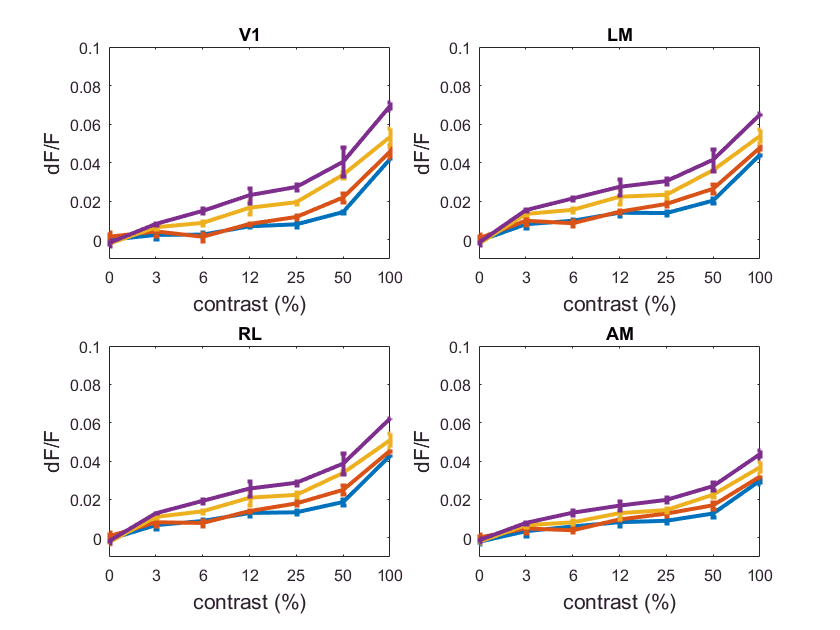


numMice = 2;
global numMice

[allSessAllPtsAllDurs_AllStates_CRF] = CRF_NOTbyBehState_noPup(nGroup,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

fntSize = 8;
fntName = 'SansSerif';
fontMult = 1.3;
subt4leg = 6;

global fntSize
global fntName
global fontMult
global subt4leg

% make duration legend
dursInSec = uniqueDurations/10;
for d = 1:length(dursInSec)

    dursInSecAsStrings = arrayfun(@num2str, dursInSec, 'UniformOutput', 0);
    
    legendStrings{d} = sprintf('%s %s', dursInSecAsStrings{d},'sec');

end 

global legendStrings; 

% plot CRFs for all durs
plotAllStates_CRF(allSessAllPtsAllDurs_AllStates_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,uniqueContrasts,uniqueDurations,durs4Legend,reigons,nGroup)

%print('n3_CRF_expt2_305RT.png','-dpng')

% CRF by BEH STATE

% RUN vs STAT

% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n});
visArea = visArea(1:4) % exclude control point
global visArea
durat = 1 % (durat = 1 means 100 ms in final set of expts)
cont = 1:length(uniqueContrasts)
n = 1:nGroup

% stat group CRF matrix
state = 'loRun'
clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF,loRun_allSessAllPtsAllDurs_CRF_err] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeStatAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

% run group CRF matrix
state = 'hiRun'
clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF_err] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

%state = loco
run_or_pup = 'run';
global run_or_pup;

reigons = {'V1','LM','RL','AM','control'};

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

numMice = 7;
global numMice

% PLOT locomotion CRF 
stateLegend = {'stat','run'};
% NOTE: CHANGE subplot dimensions if need
plotCompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

%print('group_21_CRF_noC50_errOverMice_loco.png','-dpng')

% plot scaled CRFs (loco)

yMax = 1;
yMin = 0;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

plotScaled_CompareBehState_CRF(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

%print('n21_Scaled_CRF_loco.png','-dpng')

fprintf('This is a ') ; cprintf(pea_green, 'hi pupil') ; fprintf('state\n')
fprintf('This is a ') ; cprintf(light_red, 'lo pupil') ; fprintf('state\n')

fprintf('This is a ') ; cprintf(orange, 'hi loco') ; fprintf('state\n')
fprintf('This is a ') ; cprintf(lighter_blue, 'lo loco') ; fprintf('state\n')

% annotation('textbox',[.9 .5 .1 .2], ...
%     'String','Text outside the axes','EdgeColor','none')

annotation('textbox',[.9 .5 .1 .2], ...
    'String','Text outside the axes','EdgeColor','none')

stringTest = fprintf('This is a '); cprintf(orange, 'hi loco'); fprintf('state\n');

figure
text(fprintf('This is a '); cprintf(orange, 'hi loco'); fprintf('state\n');)

sprintf(%orange, 'hi loco') fprintf('state\n'));

text(x, y, yourString, 'FontSize', 20, 'Color', 'r', 'FontWeight', 'bold');

% Lo vs Hi PUPIL

% lo pup group CRF matrix
state = 'loPup'
clear loPup_allSessAllPtsAllDurs_CRF
[loPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeLoPupAllSessAllPtsAllDurs_CRF = size(loPup_allSessAllPtsAllDurs_CRF)

% hi pup group CRF matrix
state = 'hiPup'
clear hiPup_allSessAllPtsAllDurs_CRF
[hiPup_allSessAllPtsAllDurs_CRF] = CRF_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiPupAllSessAllPtsAllDurs_CRF = size(hiPup_allSessAllPtsAllDurs_CRF)


% PLOT PUP CRF by Beh State

% state = pupil
run_or_pup = 'pup';

yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

% crf pup figs 
stateLegend = {'loPup','hiPup'}
plotCompareBehState_CRF(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

print('group_21_CRF_noC50_errOverMice_pup.png','-dpng')

% plot scaled CRFs (pup)

yMax = 1;
yMin = 0;
yLimit = [yMin yMax];
x_axis = [1:length(uniqueContrasts)];
xMax = max(x_axis);
xMin = min(x_axis);
xLimit = [xMin xMax];

plotScaled_CompareBehState_CRF(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF,durat,yMax,yMin,yLimit,x_axis,xMax,xMin,xLimit,stateLegend,uniqueContrasts,reigons,nGroup);

%print('n21_Scaled_CRF_pup.png','-dpng')

% MEAN DF vs FRAMES (Q: why do both functions take both state inputs at same 
% time when each only outputs one or the other state....? A: b/c the function is for eiather
% beh state and needs both state trial idx inputs. Note: use GLOBAL next time)

visArea = 1:4; % one area at a time, shows all contrasts (Q: could do this other way around?)
%visArea = 1:length(groupRoundXpts{1,n})
durat = 1
cont = 1:length(uniqueContrasts)

% LOCOMOTION

state = 'loRun'
[loRun_mnTraceAllConsDursPts,loRun_mnTraceStdErr] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoRun_mnTraceAllConsDursPts = size(loRun_mnTraceAllConsDursPts)

state = 'hiRun'
[hiRun_mnTraceAllConsDursPts,hiRun_mnTraceStdErr] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiRun_mnTraceAllConsDursPts = size(hiRun_mnTraceAllConsDursPts)


% for mean Trace figs

run_or_pup = 'run';

yMax = 0.1;
yMin = -0.02;
yLimit = [yMin yMax];
%x_axis = [1:length(uniqueContrasts)];
%xMax = max(x_axis);
%xMin = min(x_axis);
%xLimit = [xMin xMax];

durat = 1;

%visArea = 1:4;
visArea = 1;

% locomotion mean trace figs
stateLegend = {'stat','run'}
plotCompareBehState_mnTrace(loRun_mnTraceAllConsDursPts,hiRun_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% save plot
%print('groupLocoMnTraceV1_fig.png','-dpng')

% Mean Trace PUPIL

state = 'loPup'
[loPup_mnTraceAllConsDursPts,loPup_stdErr] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeLoPup_mnTraceAllConsDursPts = size(loPup_mnTraceAllConsDursPts)

state = 'hiPup'
[hiPup_mnTraceAllConsDursPts,hiPup_stdErr] = MnTrace_byBehState(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,groupIdxSmallPupilTrials,groupIdxLargePupilTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% con x frames x dur x points x sessions
sizeHiPup_mnTraceAllConsDursPts = size(hiPup_mnTraceAllConsDursPts)

run_or_pup = 'pup';

%visArea = 1:4;
visArea = 1;

% pupil mean trace figs
stateLegend = {'loPup','hiPup'}
plotCompareBehState_mnTrace(loPup_mnTraceAllConsDursPts,hiPup_mnTraceAllConsDursPts,cons4axes,visArea,durat,cont,yMax,yMin,yLimit,stateLegend,nGroup)

% save plot
%print('groupPupMnTraceV1_fig.png','-dpng')


% INTERP - this is for each session, (need for C50 error bars on bar chart),
% later on for the meanCRF across sessions...

durat = 1
visArea = 1:4
sess = 1:nGroup

global durat 
global visArea 
global sess 

global uniqueContrasts

yMax = 0.55;
yMin = 0;
yLimit = [yMin yMax];

% For LOCO 

[loco_lo_yi_interpedConsCurve_allPtsAllSess,loco_lo_xi_isDf_higherRes_allPtsAllSess,loco_lo_C50_allPtsAllSess,loco_lo_df_at_C50_allPtsAllSess,loco_hi_yi_interpedConsCurve_allPtsAllSess,loco_hi_xi_isDf_higherRes_allPtsAllSess,loco_hi_C50_allPtsAllSess,loco_hi_df_at_C50_allPtsAllSess] = makeC50_test(loRun_allSessAllPtsAllDurs_CRF,hiRun_allSessAllPtsAllDurs_CRF);
% the c50 output vars are pts x column w/df values at c50 x sess (probs better dimsional arrangement for this...)
loco_lo_C50_allPtsAllSess = squeeze(loco_lo_C50_allPtsAllSess);
loco_hi_C50_allPtsAllSess = squeeze(loco_hi_C50_allPtsAllSess);
% w/squeeze they are points x sess
size(loco_lo_C50_allPtsAllSess);
size(loco_hi_C50_allPtsAllSess);

% For PUPIL

[pup_lo_yi_interpedConsCurve_allPtsAllSess,pup_lo_xi_isDf_higherRes_allPtsAllSess,pup_lo_C50_allPtsAllSess,pup_lo_df_at_C50_allPtsAllSess,pup_hi_yi_interpedConsCurve_allPtsAllSess,pup_hi_xi_isDf_higherRes_allPtsAllSess,pup_hi_C50_allPtsAllSess,pup_hi_df_at_C50_allPtsAllSess] = makeC50_test(loPup_allSessAllPtsAllDurs_CRF,hiPup_allSessAllPtsAllDurs_CRF);
% the c50 output vars are pts x column w/df values at c50 x sess (probs better dimsional arrangement for this...)
pup_lo_C50_allPtsAllSess = squeeze(pup_lo_C50_allPtsAllSess);
pup_hi_C50_allPtsAllSess = squeeze(pup_hi_C50_allPtsAllSess);
% w/squeeze they are points x sess
size(pup_lo_C50_allPtsAllSess);
size(pup_hi_C50_allPtsAllSess);


numMice = 7;
global numMice

% get stderr of c50 across sessions, for all points
% for c50 error bars/bar chart
% if n>1 

% loco 

% need transpose for std to work for some reason
loco_trans_lo_C50_allPtsAllSess = loco_lo_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
loco_lo_std_C50_acrossSess_AllPts = std(loco_trans_lo_C50_allPtsAllSess);
loco_lo_stdERR_C50_acrossSess_AllPts = loco_lo_std_C50_acrossSess_AllPts/(sqrt(nGroup)); %/3);

% need transpose for std to work for some reason
loco_trans_hi_C50_allPtsAllSess = loco_hi_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
loco_hi_std_C50_acrossSess_AllPts = std(loco_trans_hi_C50_allPtsAllSess);
loco_hi_stdERR_C50_acrossSess_AllPts = loco_hi_std_C50_acrossSess_AllPts/(sqrt(nGroup)); %/3);

% pupil

% need transpose for std to work for some reason
pup_trans_lo_C50_allPtsAllSess = pup_lo_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
pup_lo_std_C50_acrossSess_AllPts = std(pup_trans_lo_C50_allPtsAllSess);
pup_lo_stdERR_C50_acrossSess_AllPts = pup_lo_std_C50_acrossSess_AllPts/(sqrt(numMice)); %/3); % number of *mice*

% need transpose for std to work for some reason
pup_trans_hi_C50_allPtsAllSess = pup_hi_C50_allPtsAllSess';
% gives std for 550 on 1 x # pts matrix
pup_hi_std_C50_acrossSess_AllPts = std(pup_trans_hi_C50_allPtsAllSess);
pup_hi_stdERR_C50_acrossSess_AllPts = pup_hi_std_C50_acrossSess_AllPts/(sqrt(numMice)); %/3);


% bar chart w/error bars across the whole group (sessions/mice), 
% what's C50 on average per area?

% LOCO

figure
Y = [mean(loco_lo_C50_allPtsAllSess(1,:),2),mean(loco_hi_C50_allPtsAllSess(1,:),2); mean(loco_lo_C50_allPtsAllSess(2,:),2), mean(loco_hi_C50_allPtsAllSess(2,:),2); mean(loco_lo_C50_allPtsAllSess(3,:),2),mean(loco_hi_C50_allPtsAllSess(3,:),2); mean(loco_lo_C50_allPtsAllSess(4,:),2),mean(loco_hi_C50_allPtsAllSess(4,:),2);]
X = [1:4];

loco_hiAndLo_StdErr = [loco_lo_stdERR_C50_acrossSess_AllPts(1,1:4); loco_hi_stdERR_C50_acrossSess_AllPts(1,1:4)];
trans_loco_hiAndLo_StdErr = loco_hiAndLo_StdErr';

h = bar(Y,'grouped');
hold on
% Find the number of groups and the number of bars in each group
[ngroups, nbars] = size(Y);
% Calculate the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, Y(:,i), trans_loco_hiAndLo_StdErr(:,i), 'k', 'linestyle', 'none');
end
%hold off

%h = bar(X,Y)
%hold on

%er1 = errorbar(Y,loco_hiAndLo_StdErr','k','LineWidth',1, 'LineStyle', 'none'); % leave out last stderr cuz its for control point    

yMin = 0;
yMax = 0.5;
ylim([0 yMax])

set(h(1),'facecolor',lighter_blue)
set(h(2),'facecolor',	[0.9100    0.4100    0.1700])

% visualization

fntSize = 10;

fntName = 'SansSerif';
set(gca, 'FontSize', fntSize, 'FontName', fntName)

ylabel('response threshold (C50)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [yMin:0.1:yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

%xlabel('contrast (%)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
areaLabels = {'V1','LM','RL','AM'};
set(gca,'xticklabel',areaLabels)

%lgd2 = legend('stationary','running');
%lgd2.FontSize = fntSize-subt4leg;

% save plot
%print('groupC50_Loco.png','-dpng')

% bar plot - W/error bars, across the whole group (sessions/mice), what's C50 on average per area?

% PUP

figure

Y = [mean(pup_lo_C50_allPtsAllSess(1,:),2),mean(pup_hi_C50_allPtsAllSess(1,:),2); mean(pup_lo_C50_allPtsAllSess(2,:),2), mean(pup_hi_C50_allPtsAllSess(2,:),2); mean(pup_lo_C50_allPtsAllSess(3,:),2),mean(pup_hi_C50_allPtsAllSess(3,:),2); mean(pup_lo_C50_allPtsAllSess(4,:),2),mean(pup_hi_C50_allPtsAllSess(4,:),2);]
X = [1:4];

pup_hiAndLo_StdErr = [pup_lo_stdERR_C50_acrossSess_AllPts(1,1:4);pup_hi_stdERR_C50_acrossSess_AllPts(1,1:4)];
trans_pup_hiAndLo_StdErr = pup_hiAndLo_StdErr';

%h = bar(X,Y)
%hold on
%er = errorbar(Y,pup_hiAndLo_StdErr','k','LineWidth',1, 'LineStyle', 'none'); % leave out last stderr cuz its for control point    

h = bar(Y,'grouped');
hold on
% Find the number of groups and the number of bars in each group
[ngroups, nbars] = size(Y);
% Calculate the width for each bar group
groupwidth = min(0.8, nbars/(nbars + 1.5));
% Set the position of each error bar in the centre of the main bar
% Based on barweb.m by Bolu Ajiboye from MATLAB File Exchange
for i = 1:nbars
    % Calculate center of each bar
    x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
    errorbar(x, Y(:,i), trans_loco_hiAndLo_StdErr(:,i), 'k', 'linestyle', 'none');
end
%hold off

yMin = 0;
yMax = 0.5;
ylim([0 yMax])

set(h(1),'facecolor',light_red)
set(h(2),'facecolor',	pea_green)

% visualization

fntSize = 10;

fntName = 'SansSerif';
set(gca, 'FontSize', fntSize, 'FontName', fntName)

ylabel('response threshold (C50)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [yMin:0.1:yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

%xlabel('contrast (%)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
areaLabels = {'V1','LM','RL','AM'};
set(gca,'xticklabel',areaLabels)

%lgd2 = legend('low pupil size','high pupil size');
%lgd2.FontSize = fntSize-subt4leg;

% save plot
%print('groupC50_Pupil.png','-dpng')


% Mean CRF Per POINT 

% This requires group matrix first...
% making mean CRF (mean CRF of all the session mean CRF's), which is needed for interp function 
% and for plotting with the interped trace

% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n});
visArea = visArea(1:4)
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)
cont = 1:length(uniqueContrasts)

% LOCO

% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 
% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
% LO BEH STATE
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts);
size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts);
% HI BEH STATE                                                                                                            
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts);
size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts);

% PUPIL

% LO BEH STATE
[loPup_mnCRF_acrossSess_AllDurAllPts,loPup_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loPup_mnCRF_acrossSess_AllDurAllPts = size(loPup_mnCRF_acrossSess_AllDurAllPts);
size_loPup_stdErrCRF_acrossSess_allPts = size(loPup_stdErrCRF_acrossSess_allPts);
% HI BEH STATE                                                                                                            
[hiPup_mnCRF_acrossSess_AllDurAllPts,hiPup_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiPup_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiPup_mnCRF_acrossSess_AllDurAllPts = size(hiPup_mnCRF_acrossSess_AllDurAllPts);
size_hiPup_stdErrCRF_acrossSess_allPts = size(hiPup_stdErrCRF_acrossSess_allPts);


% To interp across mean CRF (across all sess) - for CRF + C50 asterisk figs (dont'e need each session interp'd

% LOCO INTERP

clear loco_lo_yi_interpedConsCurve_allPts{}
clear loco_lo_xi_isDf_higherRes_allPts{} 
clear loco_lo_C50_allPts
clear loco_lo_df_at_C50_allPts

clear loco_hi_yi_interpedConsCurve_allPts{}
clear loco_hi_xi_isDf_higherRes_allPts{} 
clear loco_hi_C50_allPts
clear loco_hi_df_at_C50_allPts


global visArea
for i = visArea

    % need to output c50 for each session, input group matrix
    % 'loRun_allSessAllPtsAllDurs_CRF', which is dur x con x pt x
    % sess martix

    % take the ith CRF
    lo_nthdthith_CRF = loRun_mnCRF_acrossSess_AllDurAllPts(i,:); %(1 x 7 x 5 x 3)
    hi_nthdthith_CRF = hiRun_mnCRF_acrossSess_AllDurAllPts(i,:);

    % now we are on the CRF for 1st session, only durat, ith vis area
    % let's take the C50 for this session & vis Area 

    % INTERP - LO beh state

    % x is df vector
    x_is_df = lo_nthdthith_CRF;
    % resolution of interpolation 
    higherRes = 1/1000; 
    lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
    % the y input to inpterp() is the thing you want interpolated according to the resolution set above
    global uniqueContrasts
    y_is_cons = 1:length(uniqueContrasts); % 1-7 for crf plots (actual con values for finding C50)
    % interpolate contrast
    lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);

    % find con associated 1/2 max df/range value
    % find 1/2 max df
    % take the range of df (max df - min df)
    range = max(lo_nthdthith_CRF)-min(lo_nthdthith_CRF);
    %range = max(lo_nthdthith_CRF)-0; % range from zero (c = 1) to whatever max df response is
    % divide range by 2
    halfOf_range = range/2;
    % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
    lo_df_at_C50 = max(lo_nthdthith_CRF)-halfOf_range;

    % find C50 on interpolated curve
    % find first higher res df value greater than df_at_C50
    idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
    % use index to find associated interped CON value
    lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);

    % COLLECT LO VARS to plot
    loco_lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
    loco_lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
    loco_lo_C50_allPts(i,:) = lo_C50;
    loco_lo_df_at_C50_allPts(i,:) = lo_df_at_C50;

    % INTERP - HI beh state

    % x is df vector
    x_is_df = hi_nthdthith_CRF;
    % resolution of interpolation 
    higherRes = 1/1000; 
    hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
    % the y input to inpterp() is the thing you want interpolated according to the resolution set above
    y_is_cons = 1:length(uniqueContrasts);
    % interpolate contrast
    hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
    % find con associated 1/2 max df/range value
    % find 1/2 max df
    % take the range of df (max df - min df)

    range = max(hi_nthdthith_CRF)-min(hi_nthdthith_CRF);
    % divide range by 2
    halfOf_range = range/2;
    % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
    hi_df_at_C50 = max(hi_nthdthith_CRF)-halfOf_range;

    % find C50 on interpolated curve
    % find first higher res df value greater than df_at_C50
    idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
    % use index to find associated interped cCON value
    hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);

    % COLLECT VARS to plot
    loco_hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
    loco_hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
    loco_hi_C50_allPts(i,:) = hi_C50';
    loco_hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

end % end i loop

% PLOT INTERP + CRF, BOTH beh STATES one FIG (iterp of mean CRF, not each sess)

% LOCO

areaLabels = {'V1','LM','RL','AM'};

figure
%suptitle('locomotion')
x_axis = [1:length(uniqueContrasts)];

for i = visArea(1:4) % leave out control area
%for i = 1
    subplot(2,2,i)
    
   if nGroup == 1
            
        plot(x_axis,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),'color',lighter_blue,'LineWidth',2)
        hold on 
        %plot(loco_lo_yi_interpedConsCurve_allPtsAllSess{1,1}{i,1},loco_lo_xi_isDf_higherRes_allPtsAllSess{1,1}{i,1},'b:.')         
        %hold on
        plot(loco_lo_C50_allPtsAllSess(i,:),loco_lo_df_at_C50_allPtsAllSess(i,:),'*','color',lighter_blue,LineWidth',2)
        hold on
       
        plot(x_axis,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),'color',orange,'LineWidth',2)
        hold on 
        %plot(loco_hi_yi_interpedConsCurve_allPtsAllSess{1,1}{i,1},loco_hi_xi_isDf_higherRes_allPtsAllSess{1,1}{i,1},'r:.')
        %hold on 
        plot(loco_hi_C50_allPtsAllSess(i,:),loco_hi_df_at_C50_allPtsAllSess(i,:),'*','color',orange','LineWidth',2)
    
    else
        
        errorbar(x_axis,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'color',lighter_blue,'LineWidth',2);
        hold on 
        plot(loco_lo_C50_allPts(i,:),loco_lo_df_at_C50_allPts(i,:),'*','color',lighter_blue,'LineWidth', 2,'MarkerSize',10) 
        hold on
       
        errorbar(x_axis,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'color',orange,'LineWidth',2);
        hold on 
        plot(loco_hi_C50_allPts(i,:),loco_hi_df_at_C50_allPts(i,:),'*','color',orange,'LineWidth', 2,'MarkerSize',10)
        hold on
        
    end
    
title(areaLabels{i})
    
hold on 

%axes limits

yMax = 0.08;
yMin = -0.01;
yLimit = [yMin yMax];

xLimit = [min(x_axis) max(x_axis)];

ylim(yLimit) 
xlim(xLimit)

% axis square
 
% visualization

fntSize = 8;

fntName = 'SansSerif';
set(gca, 'FontSize', fntSize, 'FontName', fntName)

ylabel('dF/F', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [-0.1, 0, 0.02, 0.04,  0.06, yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

xlabel('contrast (%)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
xt=[x_axis];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
set(gca,'xtick',xt); 
set(gca,'xticklabel',xtl);

%stateLegend = {'stat','run'};
%lgd2 = legend([loPlot, hiPlot],'stationary','running');
%lgd2.FontSize = fntSize-subt4leg;
   
end 

%print('groupCRF_c50_Loco_fig.png','-dpng')


% To interp across mean CRF (if group, across all sess) - for CRF + C50 asterisk figs (dont'e need each session interp'd

% PUPIL 

clear pup_lo_yi_interpedConsCurve_allPts{}
clear pup_lo_xi_isDf_higherRes_allPts{} 
clear pup_lo_C50_allPts
clear pup_lo_df_at_C50_allPts

clear pup_hi_yi_interpedConsCurve_allPts{}
clear pup_hi_xi_isDf_higherRes_allPts{} 
clear pup_hi_C50_allPts
clear pup_hi_df_at_C50_allPts


global visArea
for i = visArea

    % need to output c50 for each session, input group matrix
    % 'loRun_allSessAllPtsAllDurs_CRF', which is dur x con x pt x
    % sess martix

    % take the ith CRF
    lo_nthdthith_CRF = loPup_mnCRF_acrossSess_AllDurAllPts(i,:); %(1 x 7 x 5 x 3)
    hi_nthdthith_CRF = hiPup_mnCRF_acrossSess_AllDurAllPts(i,:);

    % now we are on the CRF for 1st session, only durat, ith vis area
    % let's take the C50 for this session & vis Area 

    % INTERP - LO beh state

    % x is df vector
    x_is_df = lo_nthdthith_CRF;
    % resolution of interpolation 
    higherRes = 1/1000; 
    lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
    % the y input to inpterp() is the thing you want interpolated according to the resolution set above
    global uniqueContrasts
    y_is_cons = 1:length(uniqueContrasts);
    % interpolate contrast
    lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);

    % find con associated 1/2 max df/range value
    % find 1/2 max df
    % take the range of df (max df - min df)
    range = max(lo_nthdthith_CRF)-min(lo_nthdthith_CRF);
    %range = max(lo_nthdthith_CRF)-0; % range from zero (c = 1) to whatever max df response is
    % divide range by 2
    halfOf_range = range/2;
    % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
    lo_df_at_C50 = max(lo_nthdthith_CRF)-halfOf_range;

    % find C50 on interpolated curve
    % find first higher res df value greater than df_at_C50
    idx_df_lo_Res_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
    % use index to find associated interped CON value
    lo_C50 = lo_yi_interpedConsCurve(1,idx_df_lo_Res_aboveC50);

    % COLLECT LO VARS to plot
    pup_lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
    pup_lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
    pup_lo_C50_allPts(i,:) = lo_C50;
    pup_lo_df_at_C50_allPts(i,:) = lo_df_at_C50;

    % INTERP - HI beh state

    % x is df vector
    x_is_df = hi_nthdthith_CRF;
    % resolution of interpolation 
    higherRes = 1/1000; 
    hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
    % the y input to inpterp() is the thing you want interpolated according to the resolution set above
    y_is_cons = 1:length(uniqueContrasts);
    % interpolate contrast
    hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
    % find con associated 1/2 max df/range value
    % find 1/2 max df
    % take the range of df (max df - min df)

    range = max(hi_nthdthith_CRF)-min(hi_nthdthith_CRF);
    % divide range by 2
    halfOf_range = range/2;
    % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
    hi_df_at_C50 = max(hi_nthdthith_CRF)-halfOf_range;

    % find C50 on interpolated curve
    % find first higher res df value greater than df_at_C50
    idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
    % use index to find associated interped cCON value
    hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);

    % COLLECT VARS to plot
    pup_hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
    pup_hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
    pup_hi_C50_allPts(i,:) = hi_C50';
    pup_hi_df_at_C50_allPts(i,:) = hi_df_at_C50;
    
end % end i loop

% PLOT INTERP + CRF, BOTH beh STATES one FIG (iterp of mean CRF, not each sess)

% PUP

%areaLabels = {'V1','PL','AL','AM'};

x_axis = [1:length(uniqueContrasts)];

figure
%suptitle('pupil')

for i = visArea(1:4) % leave out control area

    subplot(2,2,i)
    
   %if nGroup == 1
            
%         plot(x_axis,loPup_mnCRF_acrossSess_AllDurAllPts(i,:),'b','LineWidth',2)
%         hold on 
%         plot(pup_lo_C50_allPts(i,:),pup_lo_df_at_C50_allPts(i,:),'b*','LineWidth',2)
%         hold on
%        
%         plot(x_axis,hiPup_mnCRF_acrossSess_AllDurAllPts(i,:),'r',2)
%         hold on 
%         plot(pup_hi_C50_allPts(i,:),pup_hi_df_at_C50_allPts(i,:),'r*','LineWidth',2)
%         hold on
%         
    %else
        
        errorbar(x_axis,loPup_mnCRF_acrossSess_AllDurAllPts(i,:),loPup_stdErrCRF_acrossSess_allPts(i,:),'color',light_red,'LineWidth',2)
        hold on 
        plot(pup_lo_C50_allPts(i,:),pup_lo_df_at_C50_allPts(i,:),'*','color',light_red,'LineWidth',2, 'MarkerSize',10)
        hold on 
        
        errorbar(x_axis,hiPup_mnCRF_acrossSess_AllDurAllPts(i,:),hiPup_stdErrCRF_acrossSess_allPts(i,:),'color',pea_green,'LineWidth',2)
        hold on 
        plot(pup_hi_C50_allPts(i,:),pup_hi_df_at_C50_allPts(i,:),'*','color',pea_green,'LineWidth',2, 'MarkerSize',10)
        hold on
        
   % end
    
%axis square     
         
title(areaLabels{i})
    
hold on 

%axes limits

yMax = 0.08;
yMin = -0.01;
yLimit = [yMin yMax];

xLimit = [min(x_axis) max(x_axis)];

ylim(yLimit) 
xlim(xLimit)

% visualization

fntSize = 8;

fntName = 'SansSerif';
set(gca, 'FontSize', fntSize, 'FontName', fntName)

ylabel('dF/F', 'FontSize', fntSize*fontMult, 'FontName', fntName)
yt = [0, 0.02, 0.04, 0.06, yMax];
ytl = arrayfun(@num2str, yt, 'UniformOutput', 0);
set(gca,'YTick',yt)
set(gca,'YTickLabel',ytl)

xlabel('contrast (%)', 'FontSize', fntSize*fontMult, 'FontName', fntName)
xt=[x_axis];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
set(gca,'xtick',xt); 
set(gca,'xticklabel',xtl);

%lgd2 = legend([loPlot, hiPlot],'low pupil state','high pupil state');
%lgd2.FontSize = fntSize-subt4leg;
  
end 

%print('groupCRF_c50_Pup_fig.png','-dpng')

% % PLOT INTERP + CRF, BOTH beh STATES one FIG (iterp of mean CRF, not each sess)
% 
% % PUPIL
% 
% % for FIGURE/Axes
% yMax = 0.1;
% yMin = -0.01;
% yLimit = [yMin yMax];
% yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];
% 
% %x_axis = [1:length(uniqueContrasts)];
% xMax = max(uniqueContrasts);
% xMin = min(uniqueContrasts);
% xLimit = [xMin xMax];
% xt=[0 0.03 0.06 0.12 0.25 0.5 1];
% xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
% %xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};
% 
% stateLegend = {'small','large'};
% 
% figure
% suptitle('pupil')
% for i = visArea(1:4) % leave out control area
% 
% %for i = 1
%     subplot(1,4,i)
%     
%    if nGroup == 1
%             
%         plot(uniqueContrasts,loPup_mnCRF_acrossSess_AllDurAllPts(i,:),'b')
%         hold on 
%         plot(pup_lo_yi_interpedConsCurve_allPtsAllSess{1,1}{i,1},pup_lo_xi_isDf_higherRes_allPtsAllSess{1,1}{i,1},'b:.')         
%         hold on
%         plot(pup_lo_C50_allPtsAllSess(i,:),pup_lo_df_at_C50_allPtsAllSess(i,:),'b*')
%         hold on
%        
%         plot(uniqueContrasts,hiPup_mnCRF_acrossSess_AllDurAllPts(i,:),'r')
%         hold on 
%         plot(pup_hi_yi_interpedConsCurve_allPtsAllSess{1,1}{i,1},pup_hi_xi_isDf_higherRes_allPtsAllSess{1,1}{i,1},'r:.')
%         hold on 
%         plot(pup_hi_C50_allPtsAllSess(i,:),pup_hi_df_at_C50_allPtsAllSess(i,:),'r*')
%     
%     else
%         
%         errorbar(uniqueContrasts,loPup_mnCRF_acrossSess_AllDurAllPts(i,:),loPup_stdErrCRF_acrossSess_allPts(i,:),'b')
%         hold on 
%         plot(pup_lo_yi_interpedConsCurve_allPts{i,1},pup_lo_xi_isDf_higherRes_allPts{i,1},'b:.')
%         hold on 
%         plot(pup_lo_C50_allPts(i,:),pup_lo_df_at_C50_allPts(i,:),'b*')
%         hold on
%        
%         errorbar(uniqueContrasts,hiPup_mnCRF_acrossSess_AllDurAllPts(i,:),hiPup_stdErrCRF_acrossSess_allPts(i,:),'r')
%         hold on 
%         plot(pup_hi_yi_interpedConsCurve_allPts{i,1},pup_hi_xi_isDf_higherRes_allPts{i,1},'r:.')
%         hold on 
%         plot(pup_hi_C50_allPts(i,:),pup_hi_df_at_C50_allPts(i,:),'r*')
%     
%     end
%     
%     ylim(yLimit) 
%     xlim(xLimit)
% 
%     ylabel('df/f')
%     xlabel('contrast (%)')
%                         
%     set(gca,'xtick',xt); 
%     set(gca,'xticklabel',xtl);
% 
%     set(gca,'YTick',yt)
%     
%     axis square
% 
% end 

%% params
nx = 100; % number of x points
xmax = 1;

% calculations
x = linspace(0, xmax, nx);
y = cos(2*pi*x);
z = sin(2*pi*x);

% visualization
figure
data_line = plot(x,y,...
    x,z,...
    'LineWidth',2)
set(data_line(2), 'LineStyle', '--');
grid on
set(gca, 'FontSize', 20, 'FontName', 'Times')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y(x)$', 'Interpreter', 'latex')
legend({'$y$','$z$'}, 'Interpreter', 'latex',...
    'Location','best')

% save plot
print('sinusoid_fig.png','-dpng')



% xh = get(gca,'xlabel') % handle to the label object
% p = get(xh,'position') % get the current position property
% p(2) = 1*p(2) ;        % double the distance, 
%                        % negative values put the label below the axis
% set(xh,'position',p) 